% B = 12;
% N = 1024;
% delta = 2/2^B;
% fs = 100E3;
% fx = fs*1/N;
% t = [0:2^B*N-1]/fs;
% y = sin(2*pi*fx*t);
% y = round(y/delta) * delta;
% s = fft(y);
% s = s(1:N/2+1);
% s = abs(s)/N;
% s(2:end-1) = 2*s(2:end-1);
% 
% f = (0:length(s) -1 )/N;
% 
% figure()
% plot(f(1:N/2+1), 20*log10(s(1:N/2+1)));

%%
% figure
% histogram(y, 2^B)
clear
tic

## 采样数据量估计

N = 16;
beta = 0.1;
Zalpha = 1.96;
Fs = 2E6;                                   % sample rate: 2MHz

% Requirements in hardware
N_record = (pi*2^(N-1)*Zalpha^2) / (beta^2);
MemorySize = N_record * 4 / 1024^2;         % unit: MB
TestTime = N_record / Fs;                   % unit: s

% UART Speed
BaudRate = 256000;
TransferTime = (MemorySize*1024^2*8 / 115200) / 3600;   % unit: hr

fprintf("Record Number: %.1f MPoints; Required Memory Size: %.1f MB;\n", N_record/1E6, MemorySize);

Record Number: 39.5 MPoints; Required Memory Size: 150.9 MB;


fprintf("Sampling Time: %.1f s; Transaction Time: %.1f hr;\n", TestTime, TransferTime);

Sampling Time: 19.8 s; Transaction Time: 3.1 hr;


## 从.mat文件中读取数据

len_seg = 125000;
index_list = [1:45, 60:198];
num_seg = length(index_list);
Vout_array = zeros([len_seg, num_seg]);
Gain = 15.2815;
j = 1;
for i = index_list
    FileName = ['./chip2-33-16/chip2-33-16-',num2str(i),'.mat'];
    data_N4 = ReadData(FileName);
    Vout_array(:, j) = Calibration(data_N4, Gain);
    if (mod(i, floor(num_seg/10)) == 0)
        fprintf("Process: %d\n", 10*i/floor(num_seg/10));
    end
    j = j + 1;
end

Process: 10
Process: 20
Process: 40
Process: 50
Process: 60
Process: 70
Process: 80
Process: 90
Process: 100
Process: 110


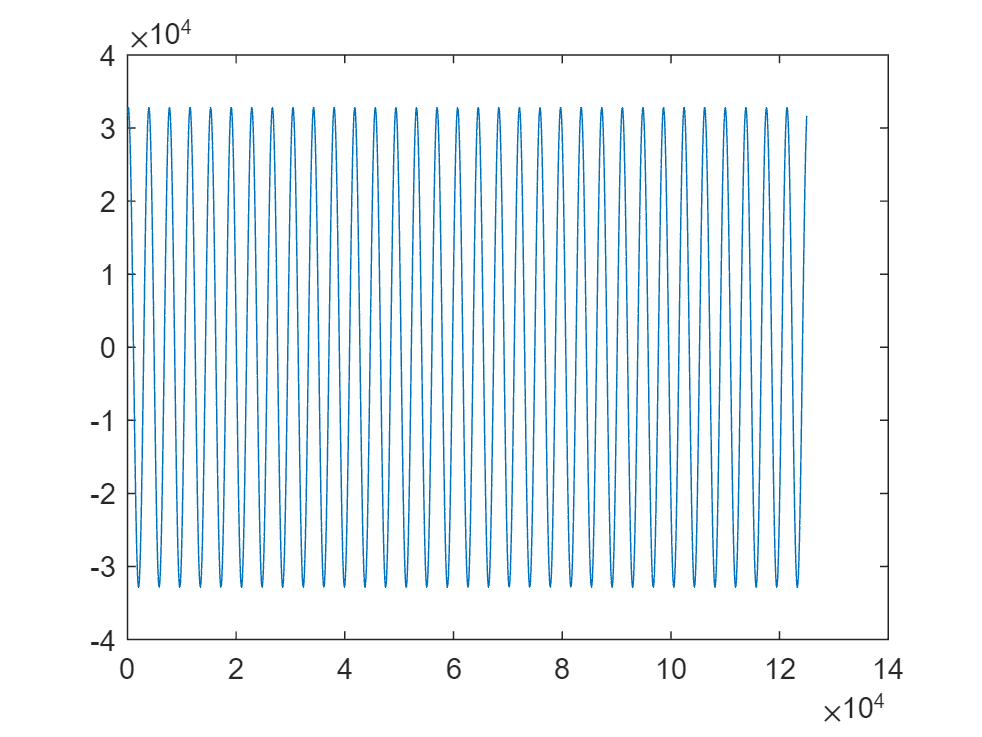




Vref = 1.8;
LSB = Vref / 2^(N-1);
MAX_CODE = 2^(N-1)-1;
MIN_CODE = -2^(N-1);

% quantization
% Negative_array = Vout_array < 0;
% quan_array = floor(Vout_array / LSB) + Negative_array;
quan_array = floor(Vout_array / LSB);
plot(quan_array(:,1))


% Remove maxcode and mincode
Max_array = quan_array>=MAX_CODE 

Max_array = 125000×184 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

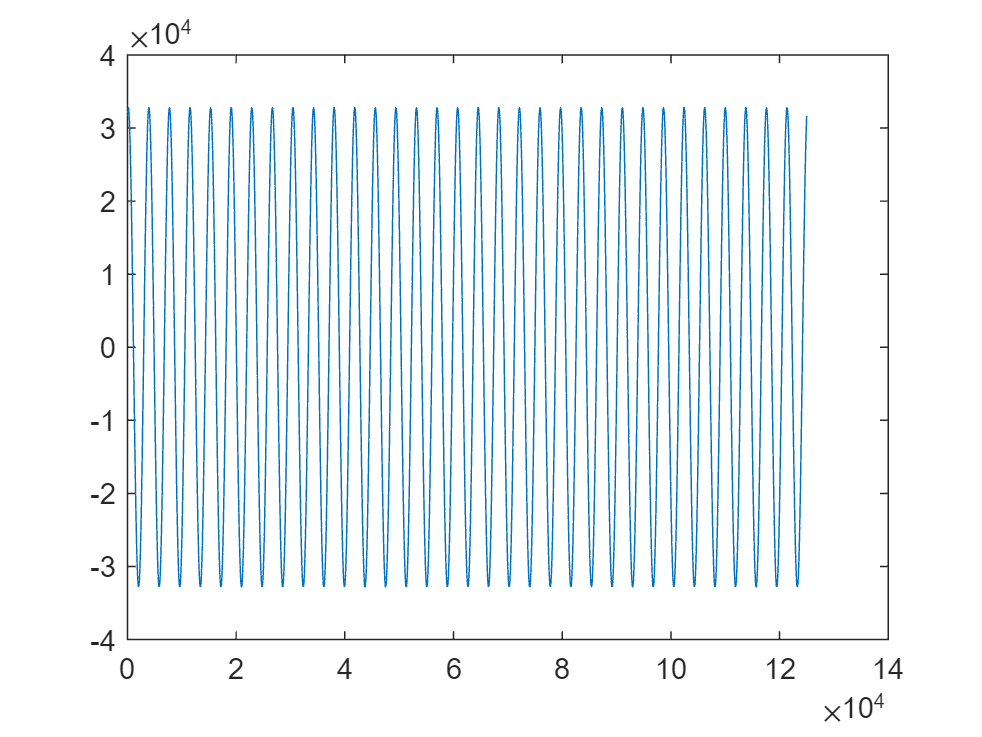

Min_array = quan_array<=MIN_CODE;
quan_array_fit = Max_array*MAX_CODE + Min_array*MIN_CODE + (~Max_array).*(~Min_array).*quan_array;

plot(quan_array_fit(:,1))



% quan_tb2 = tabulate(quan_array(:))
% quan_tb2 = array2table(quan_tb2, 'VariableNames',{'Code', 'Count', 'Percent'})


NUM_TOT = len_seg * num_seg;
quan_tb = tabulate(quan_array_fit(:));
quan_tb = array2table(quan_tb, 'VariableNames',{'Code', 'Count', 'Percent'})

quan_tb = 65536×3 table
     Code       Count       Percent 
    ______    __________    ________

    -32768    4.0157e+05      1.7459
    -32767          5778    0.025122
    -32766          2540    0.011043
    -32765          4351    0.018917
    -32764          3059      0.0133
    -32763          4676     0.02033
    -32762          3694    0.016061
    -32761          2208      0.0096
    -32760          5393    0.023448
    -32759          3678    0.015991
    -32758          2391    0.010396
    -32757          3490    0.015174
    -32756          3910       0.017
    -32755          3627     0.01577
    -32754          3613    0.015709
    -32753          5485    0.023848


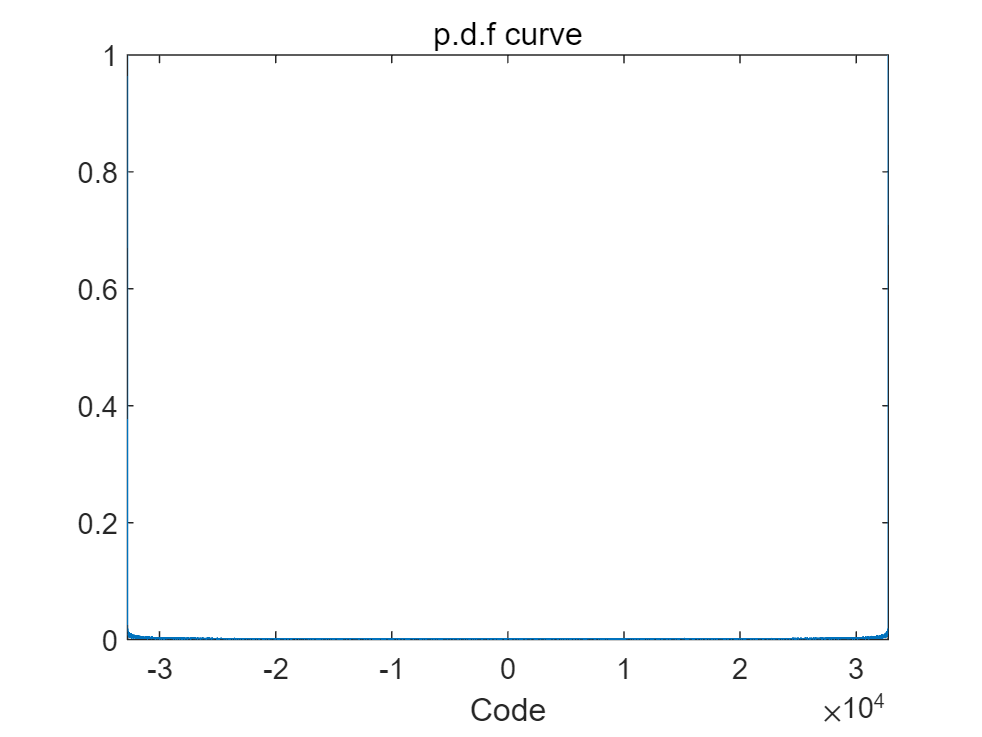


% Plot pdf curve
plot(quan_tb.Code, quan_tb.Percent);
xlabel('Code');
title('p.d.f curve');
ylim([0,1]);
xlim([MIN_CODE, MAX_CODE])


% Plot cdf curve
quan_tb.Cdf = (cumsum(quan_tb.Percent)) / 100

quan_tb = 65536×4 table
     Code       Count       Percent       Cdf   
    ______    __________    ________    ________

    -32768    4.0157e+05      1.7459    0.017459
    -32767          5778    0.025122    0.017711
    -32766          2540    0.011043    0.017821
    -32765          4351    0.018917     0.01801
    -32764          3059      0.0133    0.018143
    -32763          4676     0.02033    0.018347
    -32762          3694    0.016061    0.018507
    -32761          2208      0.0096    0.018603
    -32760          5393    0.023448    0.018838
    -32759          3678    0.015991    0.018998
    -32758          2391    0.010396    0.019102
    -32757          3490    0.015174    0.019253
    -32756          3910       0.017    0.019423
    -32755          3627     0.01577    0.019581
    -32754          3613    0.015709    0.019738
    -32753          5485    0.023848    0.019977


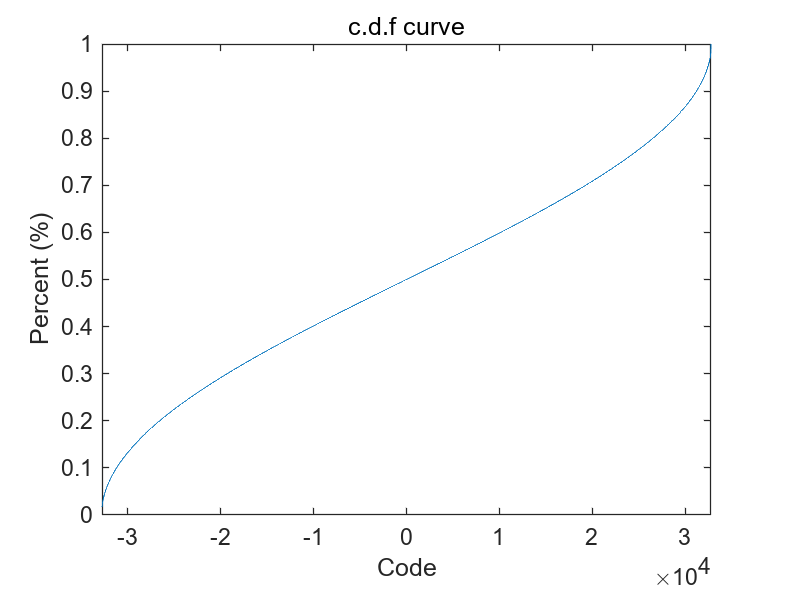

plot(quan_tb.Code, quan_tb.Cdf);
xlabel('Code');
ylabel('Percent (%)')
ylim([0,1]);
xlim([MIN_CODE, MAX_CODE])
title('c.d.f curve')


% Curve Fit for A C
a_list = zeros(1,num_seg);
c_list = zeros(1,num_seg);

t = 0:1/Fs:(len_seg-1)/Fs;

myfittype = fittype('a*sin(b*t+c)+d',...
    'dependent',{'V'},'independent',{'t'},...
    'coefficients',{'a','b','c','d'})

myfittype =      常规模型:
     myfittype(a,b,c,d,t) = a*sin(b*t+c)+d

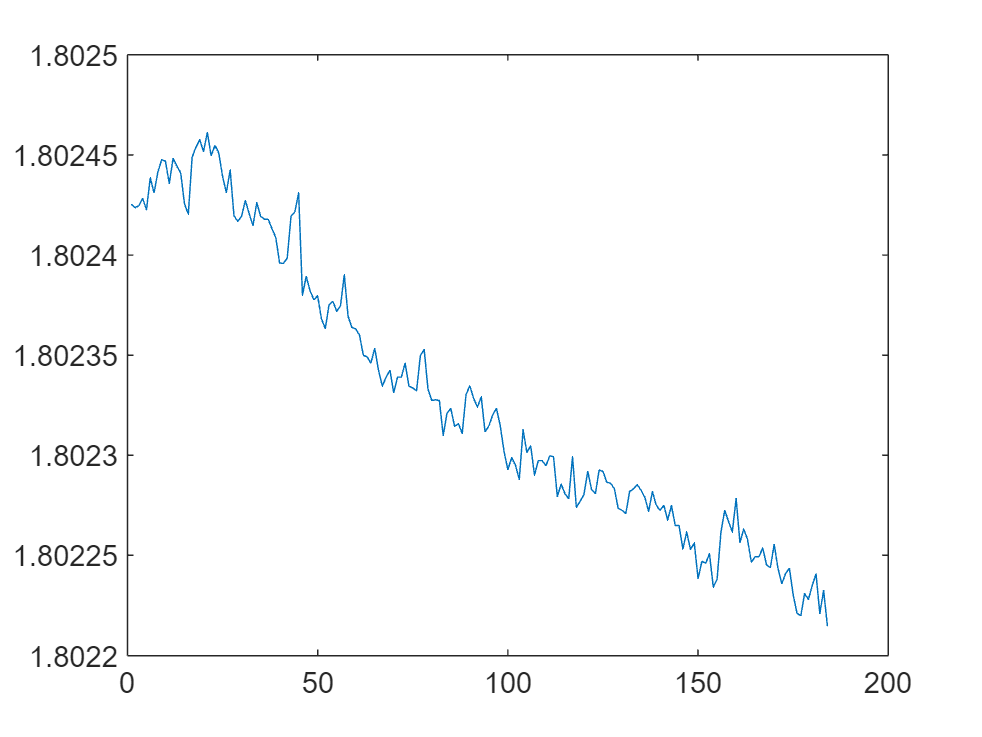

opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.StartPoint = [1.8 2*pi*33*16 0 0];

% myfit = fit(t',V1,myfittype)

for i = 1:num_seg
    V = Vout_array(:,i);
    myfit = fit(t',V,myfittype, opts);
    a_list(i) = myfit.a;
    c_list(i) = myfit.d;
end


% Display A and C
plot(abs(a_list))

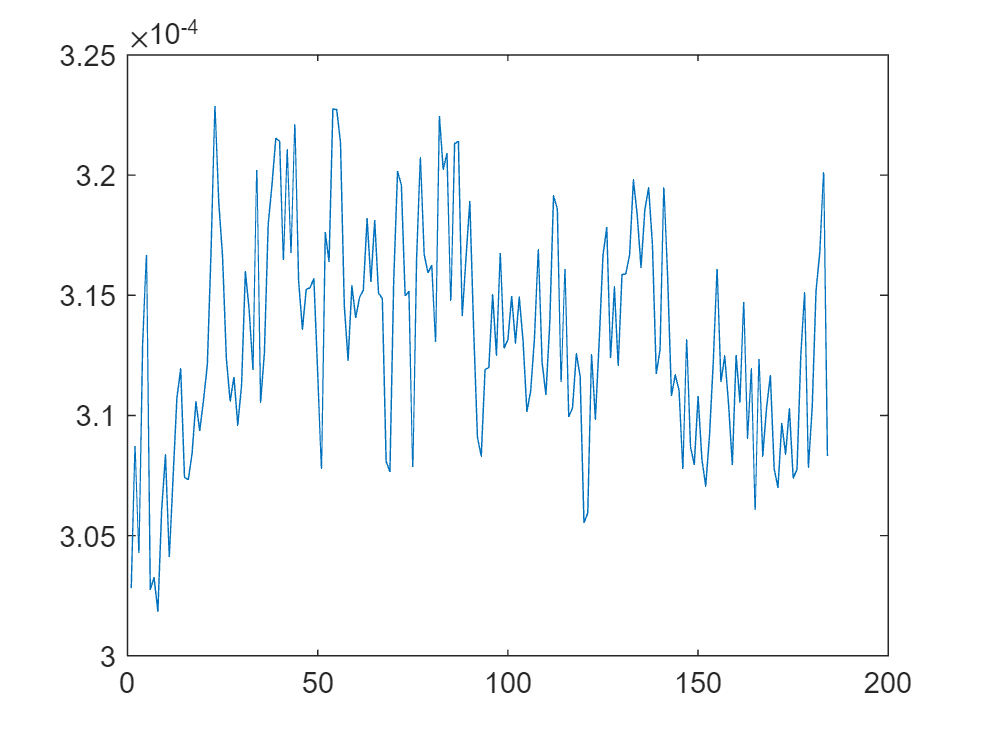

plot(abs(c_list))


% A = (max(Vout_array(:)) - min(Vout_array(:)))/2
A = mean(abs(a_list))

A = 1.8023

% C = mean(Vout_array(:))
% C = (max(Vout_array(:)) + min(Vout_array(:)))
C = mean(abs(c_list))

C = 3.1332e-04

Lm = zeros(1, 2^N-1);
for i = 1: 2^N-1
    Lm(i) = C - A*cos(pi*quan_tb.Cdf(i));
end
delta = (Lm(end) - Lm(1)) / (2^N-2)

delta = 5.4930e-05

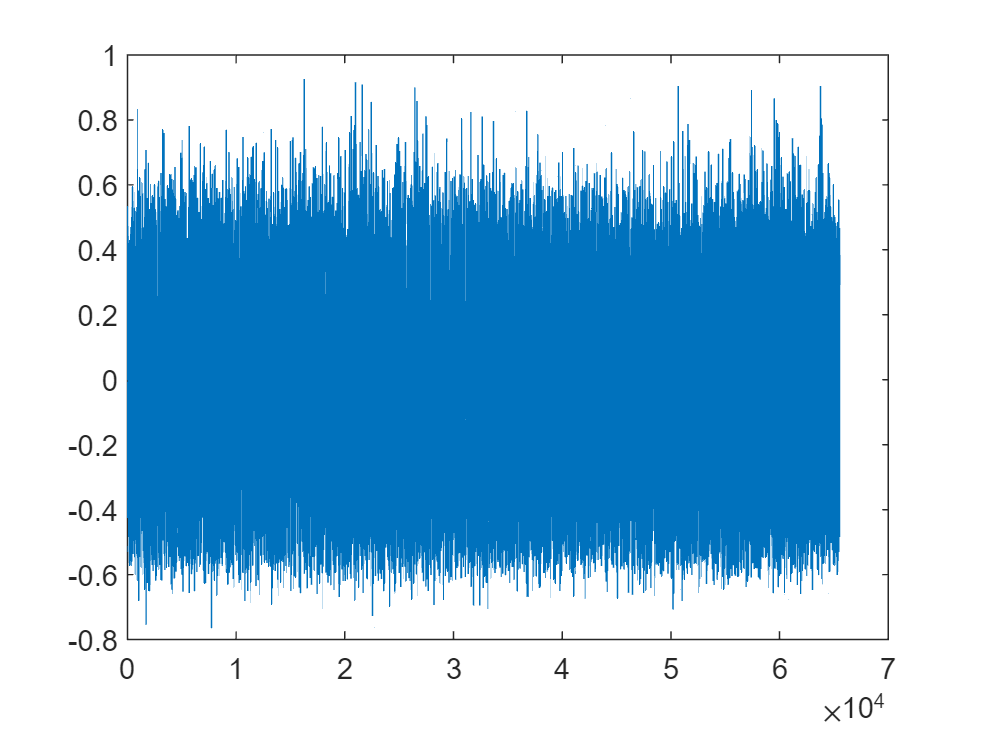


DNL = (diff(Lm) / delta) - 1;
plot(DNL)

max(abs(DNL))

ans = 0.9254

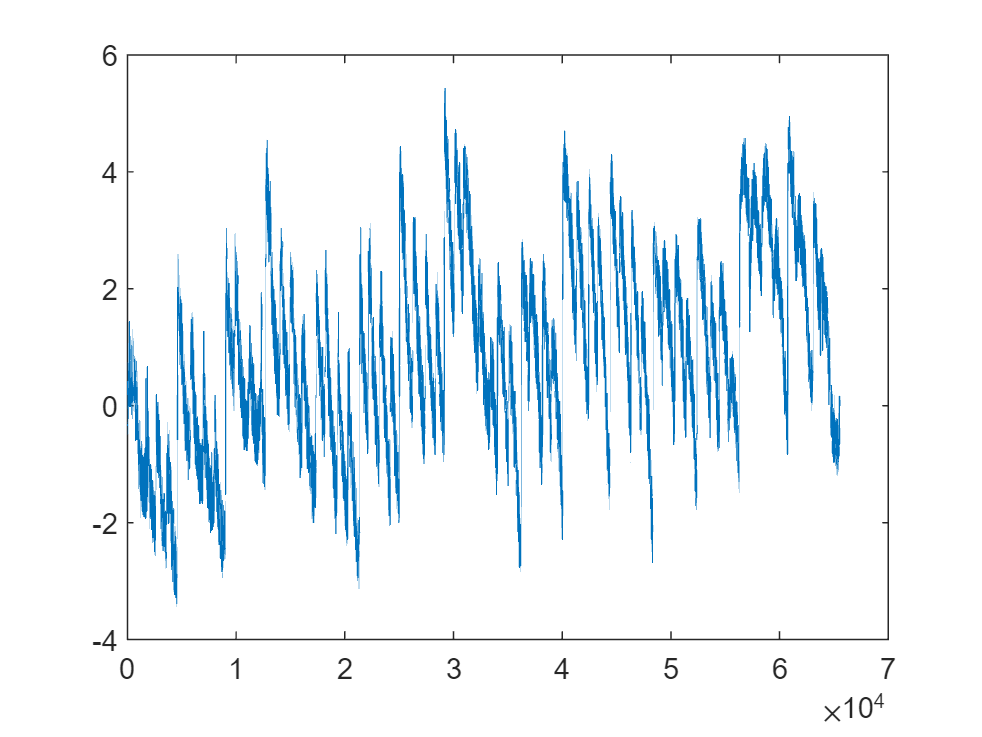

INL = cumsum(DNL);
plot(INL)

max(abs(INL))

ans = 5.4260

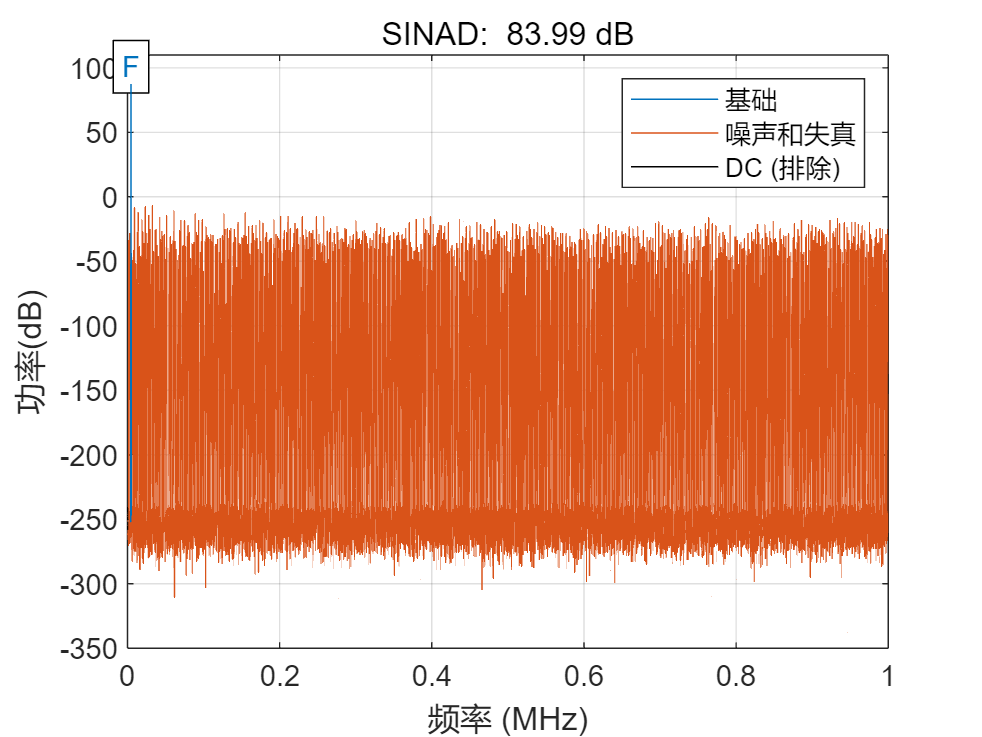


Fs = 2E6;
Fin = 4.6875E3;
N_Vin = 102400;
t = (0:N_Vin-1)/Fs;
Vamp = 1.795;
Vsin = Vamp*sin(2*pi*Fin*t);
Dout_quan = ADConversion_thres(Vsin, Lm);
Vsin_quan = ((Dout_quan/2^N)-0.5)*2*Vamp; 
% plot(t,[Vsin; Vsin_quan])
sinad(Dout_quan, Fs);

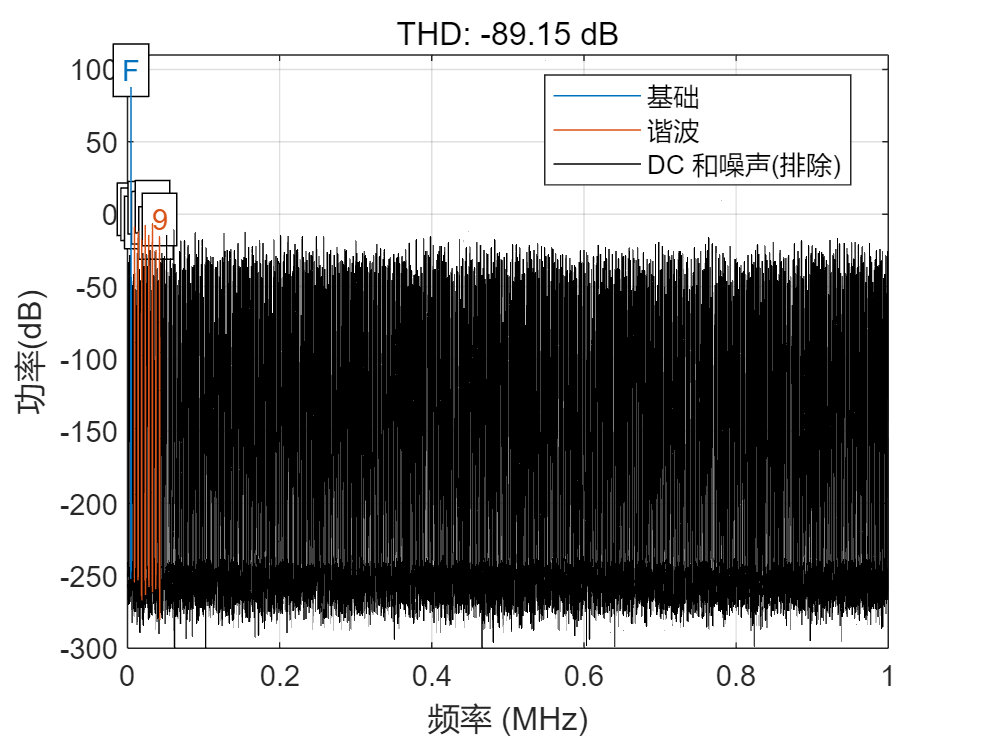

ans = -89.1491

thd(Dout_quan, Fs, 9, 'aliased')


% D1 = zeros(1, 2^N-1);
% L1 = zeros(1, 2^N-1);
% for i = 1:2^N-2
%     D1(i) = (2^N-2)*(cos(pi*quan_tb.Cdf(i))-cos(pi*quan_tb.Cdf(i+1))) / ...
%         (cos(pi*quan_tb.Cdf(1))-cos(pi*quan_tb.Cdf(2^N-1))) - 1;
%     L1(i) = (2^N-2)*(cos(pi*quan_tb.Cdf(1))-cos(pi*quan_tb.Cdf(i))) / ...
%         (cos(pi*quan_tb.Cdf(1))-cos(pi*quan_tb.Cdf(2^N-1))) - i;
% 
% end
% plot(D1)
% plot(L1)
% max(abs(L1))
% toc


function [dnl,inl] = dnl_inl_sin(y)
    %DNL_INL_SIN
    % dnl and inl ADC output
    % input y contains the ADC output
    % vector obtained from quantizing a
    % sinusoid
    % Boris Murmann, Aug 2002
    % Bernhard Boser, Sept 2002
    % histogram boundaries
    minbin=min(y);
    maxbin=max(y);
    % histogram
    h = hist(y, minbin:maxbin);
    % cumulative histogram
    ch = cumsum(h);

    % transition levels found by:
    T = -cos(pi*ch/sum(h));
    % linearized histogram
    hlin = T(2:end) - T(1:end-1);
    % truncate at least first and last
    % bin, more if input did not clip ADC
    trunc=2;
    hlin_trunc = hlin(1+trunc:end-trunc);
    % calculate lsb size and dnl
    lsb= sum(hlin_trunc) / (length(hlin_trunc));
    dnl= [0 hlin_trunc/lsb-1];
    misscodes = length(find(dnl<-0.99));
    % calculate inl
    inl= cumsum(dnl);
end

function data_N4 = ReadData(filename)
    LSB_sub = 1.8 / 2^5;
    data_origin = importdata(filename);
    data_bin = dec2bin(data_origin);
    
    % ????????
    data_sign = bin2dec(data_bin(:,1));
    data_value = bin2dec(data_bin(:,2:end));
    data_sign(data_sign==1) = -1;
    data_sign(data_sign==0) = 1; 
    
    data_value = data_value .* data_sign;
    
    % ??????????????????
    len = length(data_value) / 4;
    data_N4 = reshape(data_value, [4, len])';

    data_N4 = data_N4 * LSB_sub;
end

function Vout_calib = Calibration(data_N4, Gain)
    Vout_calib = zeros(length(data_N4), 1);
    for i = 1:length(data_N4)
        Vout_calib(i) = Calib_Gain(data_N4(i,:), Gain);
    end
end

function V_calib = Calib_Gain(V_uncalib, GainA)
    l = length(V_uncalib);
    V_calib = 0;
    for i = 1:l
        V_calib = V_calib + V_uncalib(i) / GainA^(i-1);
    end    

end
